# Mass spring damper model equation (function)

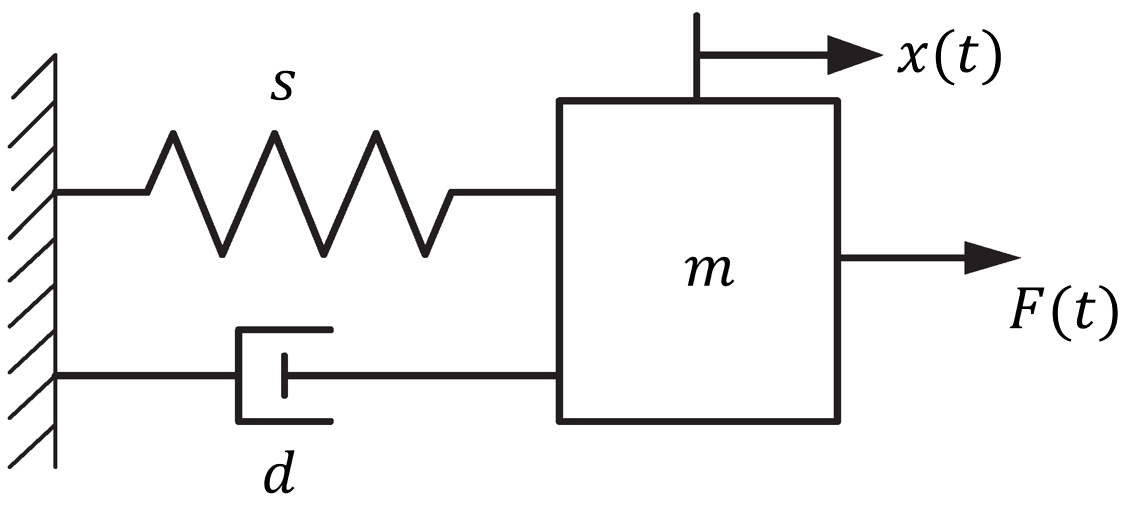


$$\dot X = \mathbf{A}\cdot X + \mathbf{B} \cdot u = 
\left[ \matrix{0 & 1 \cr -\frac{s}{m} & -\frac{d}{m}} \right] \left[ \matrix{x \cr \dot x} \right] + \left[ \matrix{0 \cr \frac{1}{m}} \right] F$$


function dX = massDamperSpringEquation(t, X, modelParamStruct, modelInput)

### Getting model parameters from struct

m = modelParamStruct.MASS; % [kg] mass
d = modelParamStruct.DAMPER_CONST; % [N.s/m] damper constant
s = modelParamStruct.SPRING_CONST; % [N/m] spring constant

### Computing the input value based on interpolation

The solver may try to solve the equation at a given time when the input is not specified. In this case, the actual input is provided by linear interpolation between the two closest data.

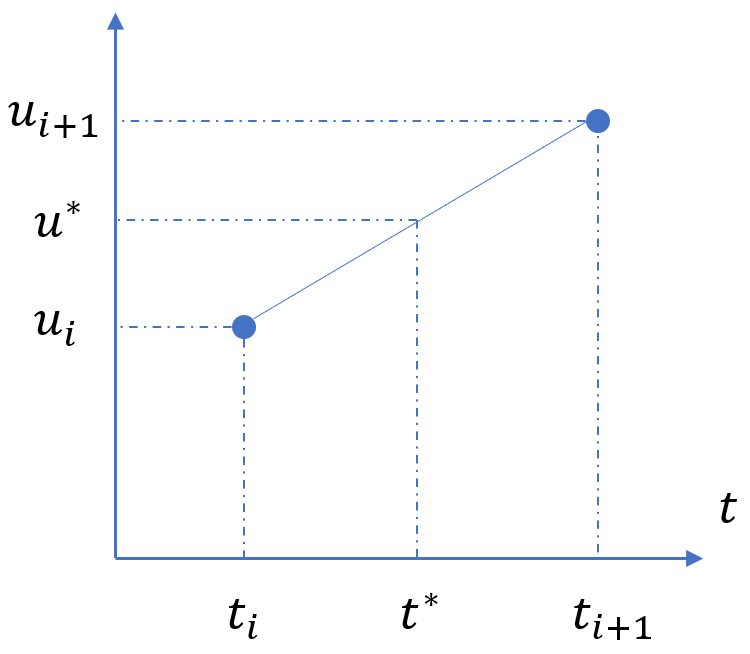

timeVect = modelInput.timeVect;
inputVect = modelInput.inputVect;
u = interp1(timeVect, inputVect, t);

### State representation of the model

#### State transition matrix

A = [  0,    1         % velocity
     -s/m, -d/m;];     % acceleration (Newton II law)

#### Input matrix

B = [  0        % input has no indirect effect to the velocity
     1 / m;];   % acceleration (Newton II law)       

#### State-space model

dX = A * X + B * u;
end